# Speech-To-Text

### Download audio

% Download the MP3 from GitHub
audioURL  = "https://github.com/yanndebray/programming-GPTs/raw/refs/heads/main/data/audio/enYann-tale_of_two_cities.mp3";
fileName  = "enYann-tale_of_two_cities.mp3";
websave(fileName, audioURL);
[audio, fs] = audioread(fileName);
sound(audio,fs)

### Whisper

To run Whisper locally, you must first download the model and unzip it in a location on the path. A doc example provides a script that can be adapted for different sizes of the model.

% openExample('audio/DownloadWhisperSpeechtoTextModelExample')
modelSize = "base";
downloadLink = "https://ssd.mathworks.com/supportfiles/audio/whisper-"+modelSize+".zip";

transcript = "It was the best of times. It was the worst of times. It was the age of wisdom. It was the age of foolishness. It was the epoch of belief. It was the epoch of incredulity. It was the season of light. It was the season of darkness. It was the spring of hope. It was the winter of despair. We had everything before us. We had nothing before us. We were all going direct to heaven. We were all going direct the other way. In short, the period was so far like the present period that some of its noisiest authorities insisted on its being received for good or for evil in the superlative degree of comparison only."

downloadFolder = fullfile(tempdir,"whisperDownload");
loc = websave(downloadFolder,downloadLink);
modelsLocation = "models";
% modelsLocation = tempdir;
unzip(loc,modelsLocation)
addpath(fullfile(modelsLocation,"whisper-"+modelSize))

client = speechClient("whisper","ModelSize","base"); 
transcript = speech2text(audio, fs, Client=client)

T = 132×2 table
    Transcript    Confidence
    __________    __________

     "and"         0.71934  
     "it"           0.9986  
     "was"         0.55658  
     "the"         0.78165  
     "best"        0.75782  
     "of"          0.93973  
     "times"       0.77237  
     "it"          0.86988  
     "was"         0.93781  
     "the"         0.74963  
     "worst"       0.77102  
     "of"          0.99338  
     "times"        0.7899  
     "it"          0.50576  
     "was"         0.70167  
     "the"         0.91562  


### wav2vec 2.0

You can compare the whisper transcription with another model wav2vec2.0

% openExample('audio/DownloadWav2vecExample')
downloadLink = "https://ssd.mathworks.com/supportfiles/audio/asr-wav2vec2-librispeech.zip";

ans = "and it was the best of times it was the worst of times it was the age of wisdom it was the age of foolishness ah it was th the epoch of belief and it was the epoch of incredulity it was the season of light it was the season of darkness it was the spring of hope it was the winter of a despair and we had everything before us an we had nothing before us we were all going direct to heaven and we were all going direct the other way a in short the period was so far like the present period a that a some of its noisiest authorities a insisted on its being received for good or for evil and in the superlative degree of comparison only"

downloadFolder = fullfile(tempdir,"wav2vecDownload");
loc = websave(downloadFolder,downloadLink);
modelsLocation = "models";
% modelsLocation = tempdir;
unzip(loc,modelsLocation)
addpath(fullfile(modelsLocation,"asr-wav2vec2-librispeech"))

client = speechClient("wav2vec2.0"); 
T = speech2text(audio, fs, Client=client)

strjoin(T.Transcript," ")

### Signal Labeler

[Label Spoken Words in Audio Signals - MATLAB & Simulink](https://www.mathworks.com/help/signal/ug/label-spoken-words-in-audio-signals-using-external-api.html)

signalLabeler

transcription2 =   Python Transcription with properties:

         model_extra: [1x1 py.dict]
    model_fields_set: [1x1 py.set]
            logprobs: [1x1 py.NoneType]
                text: [1x605 py.str]

    Transcription(text='It was the best of times. It was the worst of times. It was the age of wisdom. It was the age of foolishness It was the the epoch of belief It was the epoch of incredulity. It was the season of light. It was the season of darkness It was the spring of hope. It was the winter of despair. We had everything before us We had nothing before us. We were all going direct to heaven We were all going direct the other way In short the period was so far like the present period that some of its noisiest authorities Insisted on its being received for good or for evil in the superlative degree of comparison only', logprobs=None)


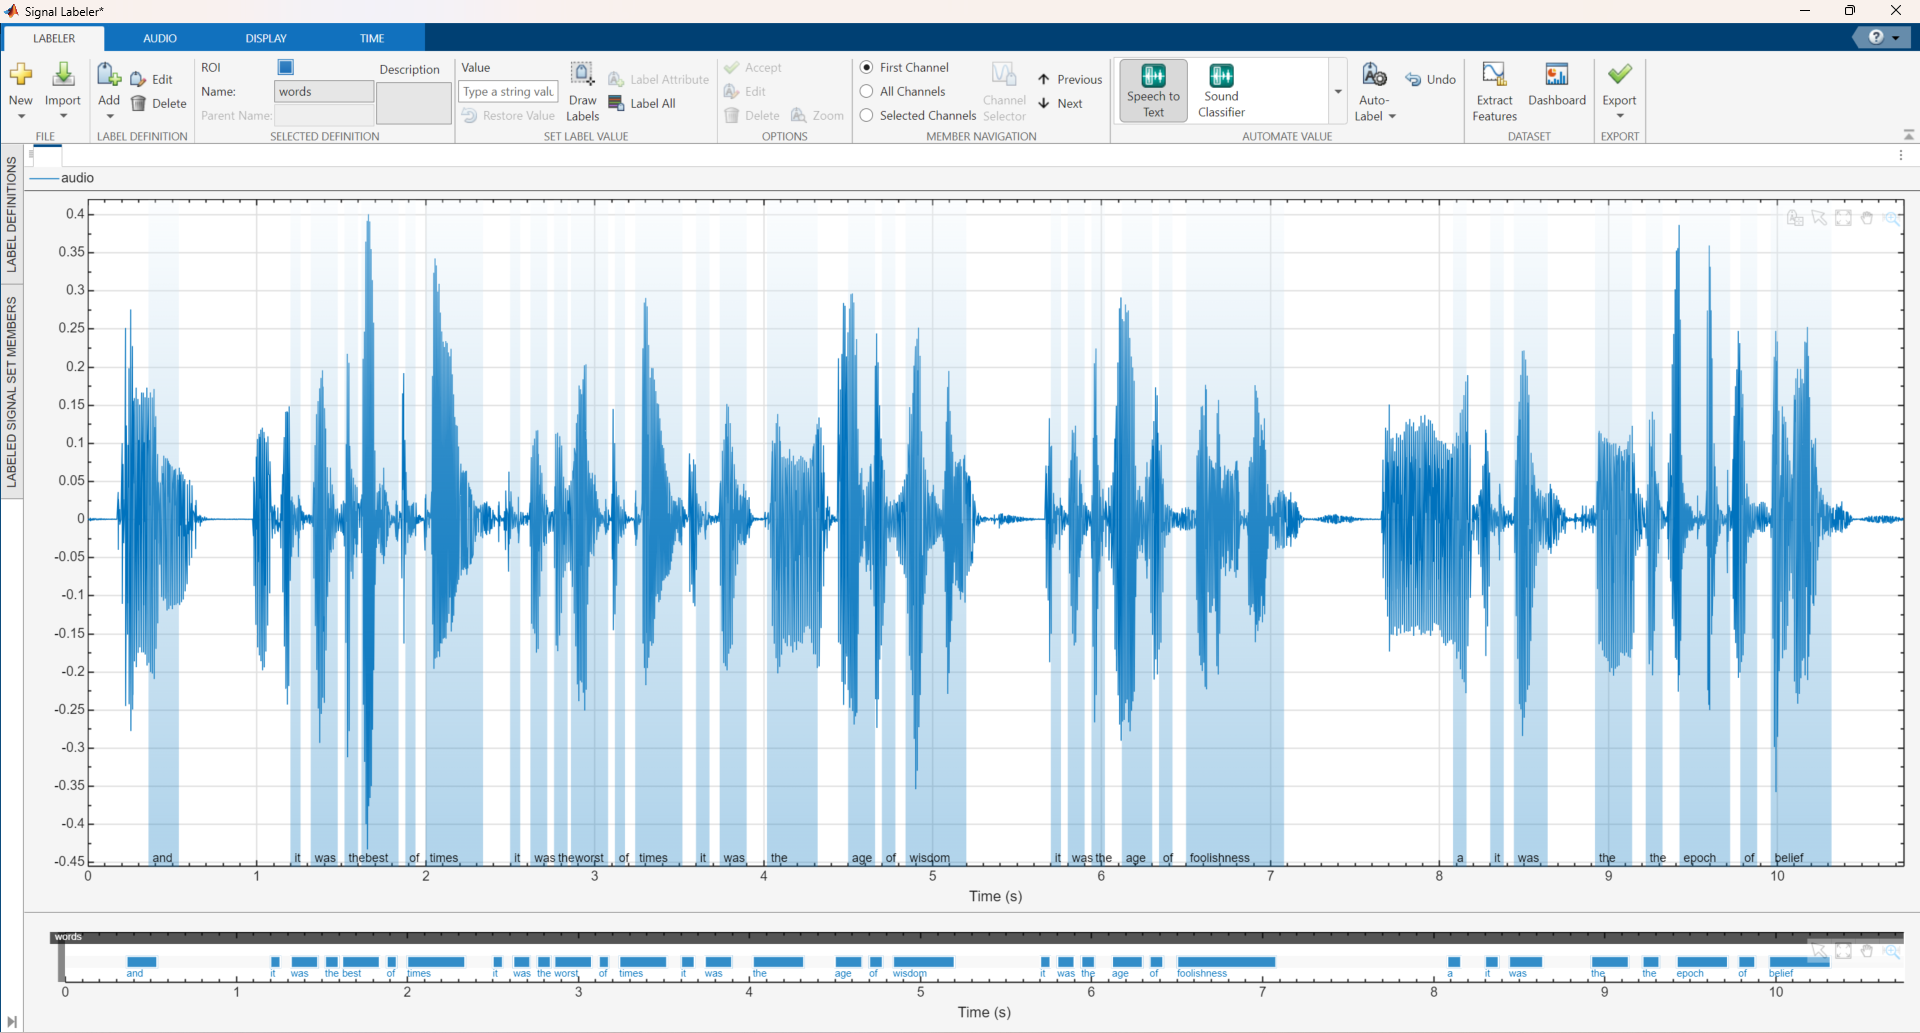

### OpenAI API

Let's use the Python OpenAI package to call the hosted whisper model

% Python code input
pycode = [...
"import openai",...
"from pathlib import Path",...
"file_path = Path(fileName)",...

ans =   Python str with no properties.

    It was the best of times. It was the worst of times. It was the age of wisdom. It was the age of foolishness It was the the epoch of belief It was the epoch of incredulity. It was the season of light. It was the season of darkness It was the spring of hope. It was the winter of despair. We had everything before us We had nothing before us. We were all going direct to heaven We were all going direct the other way In short the period was so far like the present period that some of its noisiest authorities Insisted on its being received for good or for evil in the superlative degree of comparison only


"transcription = openai.audio.transcriptions.create(model=""whisper-1"", file=file_path)"...
];

try
    [transcription2] = pyrun(pycode, ...
         [ "transcription" ], "fileName", fileName)
catch ME
    % Clear temporary variables from workspace and from Python
    clear pycode;
    if ME.identifier == "MATLAB:Python:PyException"
        pyrun("del fileName");
    end
    rethrow(ME)
end

% Clear temporary variables from workspace and from Python
clear pycode;
pyrun("del fileName");

transcription2.text